# Introduction to System Modeling with Simulink, the use of the Live Editor and Virtual Labs

## 1. Simulink Basics

### Intro

[**Simulink**](https://www.mathworks.com/products/simulink.html) is a block diagram environment for multidomain time simulation. It supports system-level design, simulation, automatic code generation, and continuous test and verification of embedded systems The aforementioned concepts are the basics of the Model-Based Design which systematically uses virtual models throughout your development process.

Simulink provides a graphical editor, customizable block libraries, and solvers for modeling and simulating dynamic systems. 

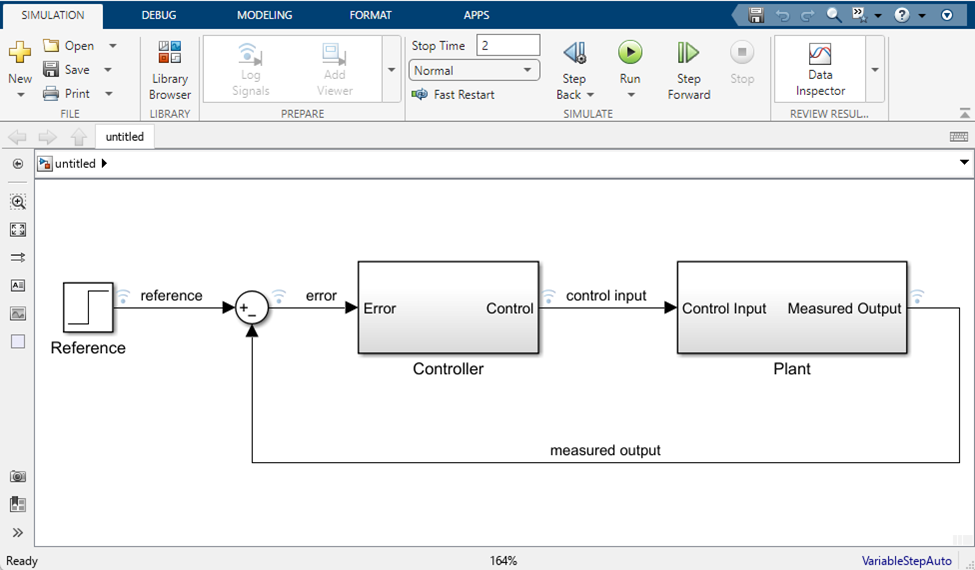

Simulink handles data in three categories:

- **Signals **— Block inputs and outputs, computed during simulation

- **States** — Internal values, representing the dynamics of the block, computed during simulation

- **Parameters** — Values that affect the behavior of a block, controlled by the user

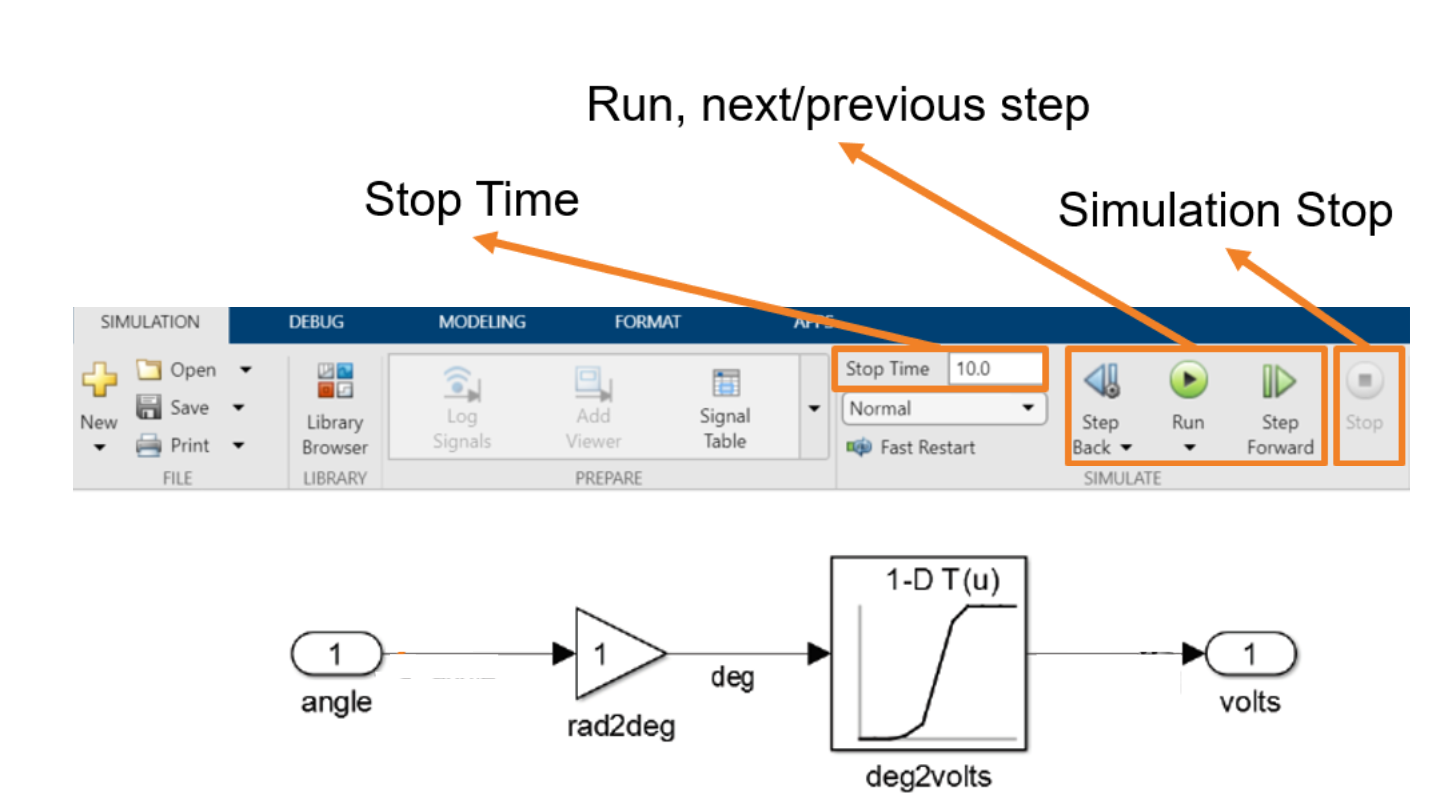

### Simulink and MATLAB

Simulink is integrated with MATLAB, enabling you to incorporate MATLAB algorithms into models and export simulation results to MATLAB for further analysis.

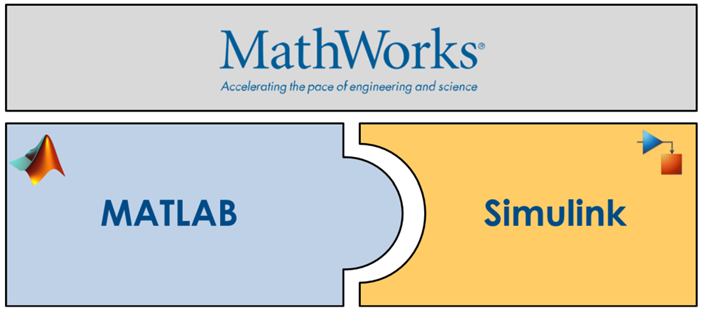

Simulink is built on top of MATLAB, it is one of the many tools (together with many Toolboxes) that are provided with MATLAB.

- **Simulink **makes simulations easier to achieve, by using blocks that correspond to codes you don't see. With Simulink, the model of the system you want to simulate is more readable, because it's represented by graphics.

- **MATLAB **is a high-level language for algorithm programming (even though today is something more articulated). With MATLAB you can implement line of codes to program your own routines or re-use those already provided (aka functions).

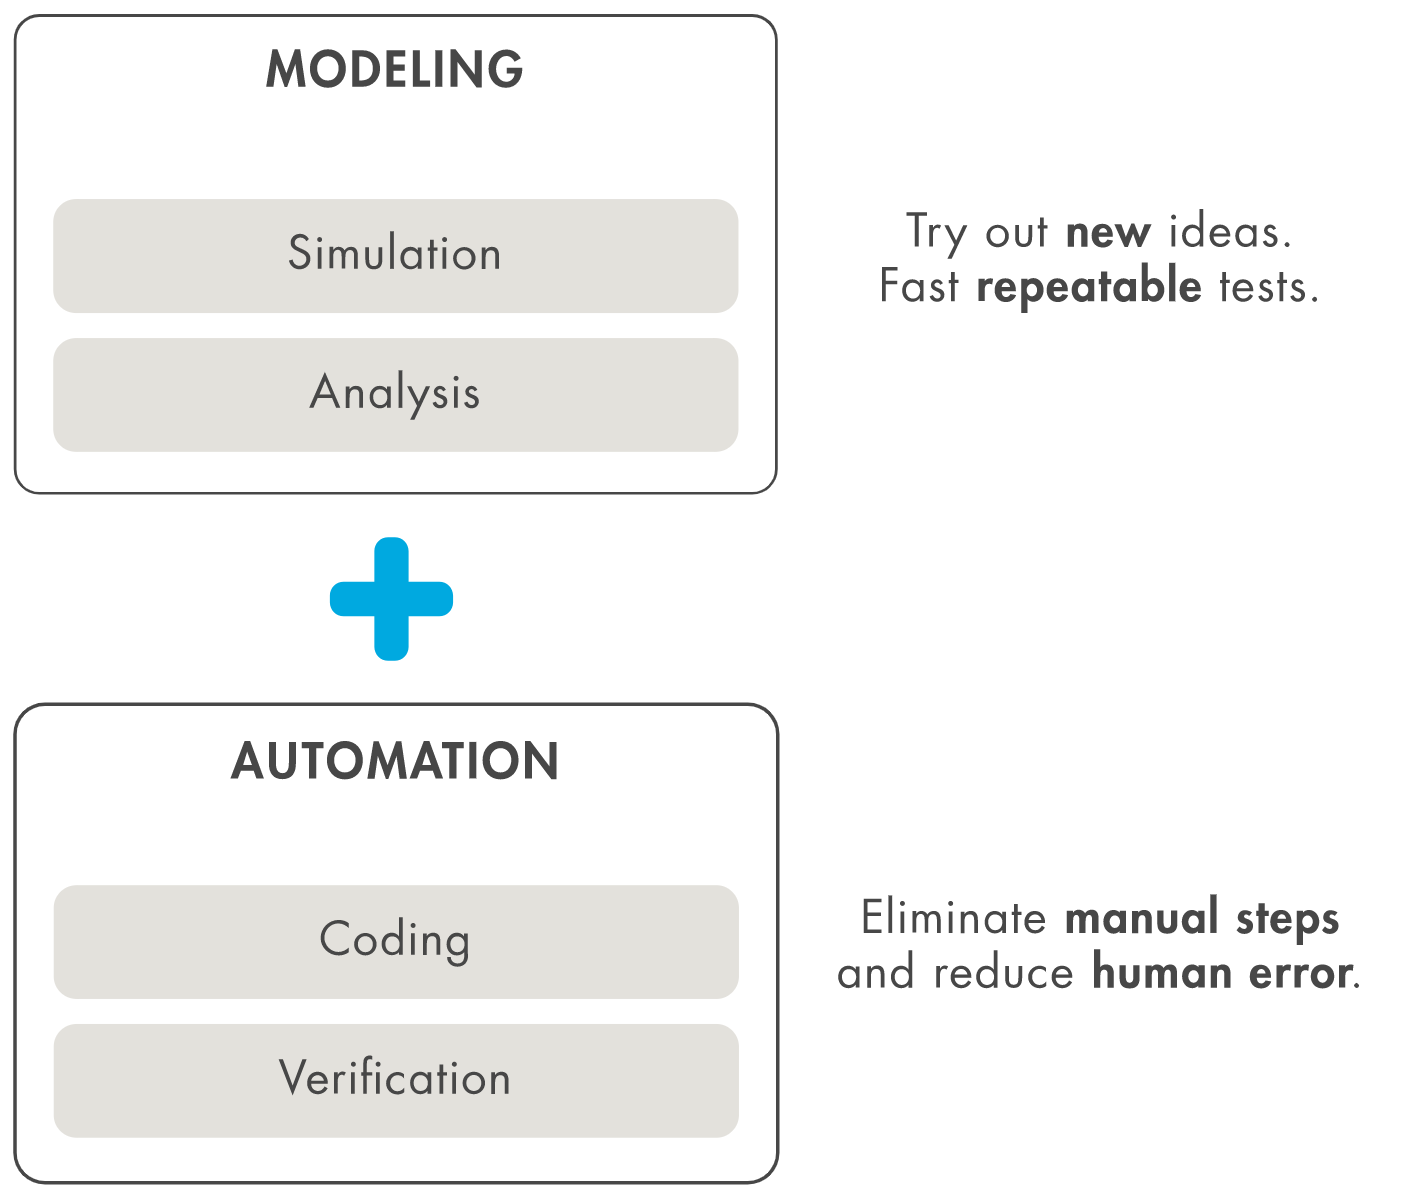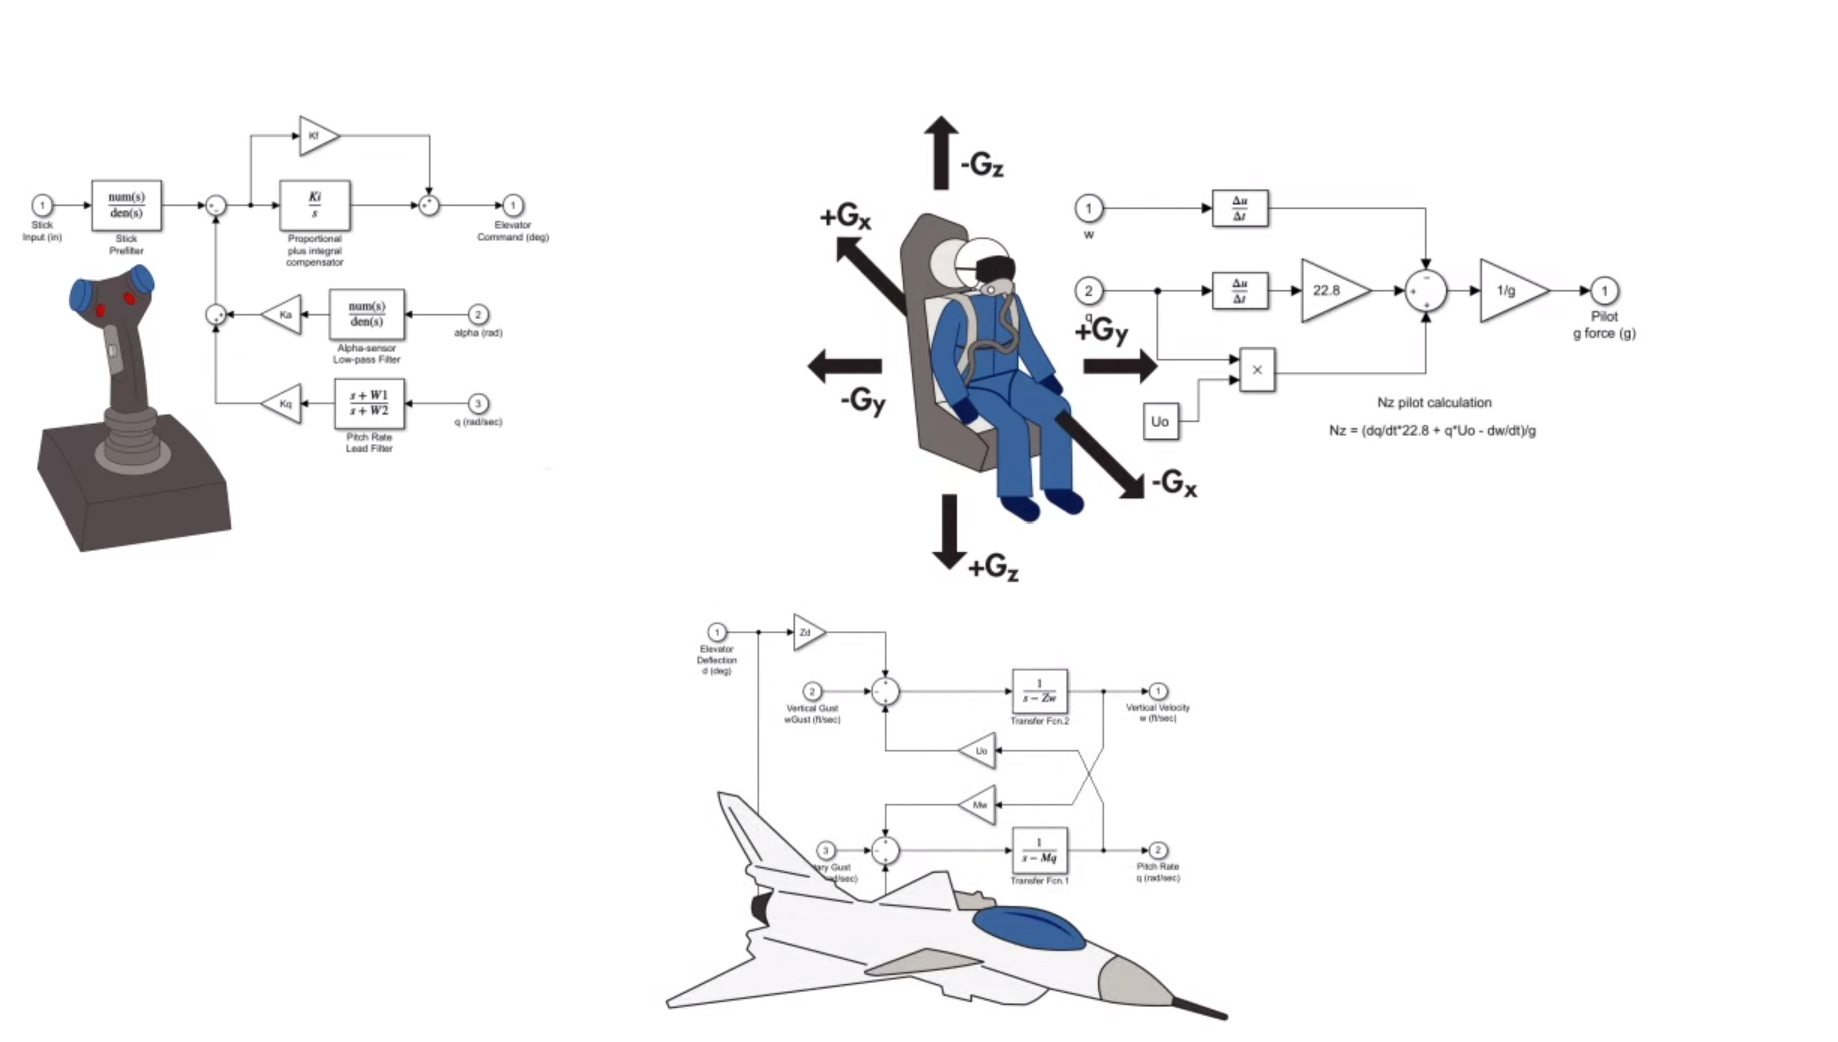

### How to ramp-up in Simulink?

Why Simulink? Simulink is today used in many applications fields (automotive, power electronics, electrifications, digital twins) by top-class companies (check these [user stories](https://www.mathworks.com/company/customer-stories/search.html?q=&page=1) or [technical articles](https://www.mathworks.com/company/technical-articles.html?q=&page=1)).

With Simulink (and MATLAB) you can have one integrated tool chain from the beginning of development to the end, have clear traceability of requirements, easy maintain the software because it is implemented as a model from which automatically generate code.

If you don't know Simulink, you can ramp-up according to the following plan:

- Online Training (2h) - [Simulink Onramp](https://www.mathworks.com/learn/tutorials/simulink-onramp.html)

- Video Series (<50min) - [Getting Started with Simulink](https://www.mathworks.com/videos/series/getting-started-with-simulink.html)

- Video (<12min) - [Getting Started with Simulink for Controls](https://www.mathworks.com/videos/getting-started-with-simulink-69027.html)

- Video (<13min) - [Getting Started with Simulink for Signal Processing](https://www.mathworks.com/videos/getting-started-with-simulink-for-signal-processing-1586429627003.html)

- [Webpage](https://www.mathworks.com/products/simulink.html)

## 2. Mathematical models

The first step in the control design process is to develop appropriate mathematical models of the system to be controlled. These models may be derived either from physical laws or experimental data. In this interactive live script, we quickly review the models of the two classical dynamic systems developed in the [Introduction: System Modeling](https://ctms.engin.umich.edu/CTMS/index.php?example=Introduction&section=SystemModeling) web page, a simple mass-spring-damper system. In this page, we investigate the time response of these two systems for different system parameters and different inputs. Investigating these two systems will help us to better understand the more complex systems that we investigate elsewhere in the [Controls Tutorial](https://ctms.engin.umich.edu/CTMS/index.php?aux=Home) website and in the other live script pages. Having a model and understanding a system's dynamics helps us in the process of designing its controller.

Key MATLAB commands used in this tutorial are: [`ss`](http://www.mathworks.com/help/toolbox/control/ref/ss.html) ,  [`tf`](http://www.mathworks.com/help/toolbox/control/ref/tf.html)

### Example: Mass-Spring-Damper System

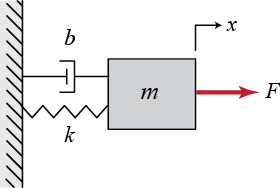

The free-body diagram for this system is shown below. The spring force is proportional to the displacement of the mass, $x$, and the viscous damping force is proportional to the velocity of the mass, $v=\dot{x}$. Both forces oppose the motion of the mass and are, therefore, shown in the negative $x$-direction. Note also that $x=0$ corresponds to the position of the mass when the spring is unstretched. 

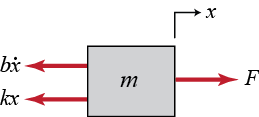

Now we proceed by summing the forces and applying Newton’s second law, in each direction. In this case, there are no forces acting in the$y$-direction; however, in the $x$-direction we have:


$$
\Sigma F_x = F(t) - b \dot{x} - k x = m \ddot{x}
$$
   

This equation, known as the **governing equation**, completely characterizes the dynamic state of the system. Later, we will see how to use this to calculate the response of the system to any external input, $F(t)$, as well as to analyze system properties such as stability and performance. 

To determine the **state-space representation** of the mass-spring-damper system, we must reduce the second-order governing equation to a set of two first-order differential equations. To this end, we choose the position and velocity as our state variables. 


$$
\mathbf{x} = \left[ \begin{array}{c} x \\ \dot{x} \end{array}\right]
$$


The position variable captures the potential energy stored in the spring, while the velocity variable captures the kinetic energy stored by the mass. The damper only dissipates energy, it doesn't store energy. Often when choosing state variables it is helpful to consider what variables capture the energy stored in the system. 

The state equation in this case is:


$$
\mathbf{\dot{x}} = \left[ \begin{array}{c} \dot{x} \\ \ddot{x} \end{array} \right] = \left[ \begin{array}{cc} 0 & 1 \\ -\frac{k}{m}  & -\frac{b}{m} \end{array} \right] \left[ \begin{array}{c} x \\ \dot{x} \end{array} \right] + \left[ \begin{array}{c} 0 \\ \frac{1}{m} \end{array} \right] F(t)
$$


If, for instance, we are interested in controlling the position of the mass, then the output equation is:


$$
y = \left[ \begin{array}{cc} 1 & 0 \end{array} \right] \left[ \begin{array}{c} x \\ \dot{x} \end{array} \right]
$$


Rearranging the original governing equation, we arrive at the equivalent differential equation model where we understand the left-hand side of the equation captures the natural dynamics of the system, while the right-hand side is the forcing input for the system. 


$$
m \ddot{x}  + b \dot{x} + k x = F(t)
$$


An alternative model called the **transfer function** can be found by taking the model into the Laplace domain and then rearranging it into the form output divided by input. Taking the Laplace transform of the above equation assuming zero initial conditions:


$$
m s^2 X(s) + b s X(s) + k X(s) = F(s)
$$


and then rearranging assuming a force input and displacement output results in the following transfer function:


$$
\frac{X(s)}{F(s)} = \frac{1}{m s^2 + b s + k}
$$


### System Free Response

Now we will demonstrate how to create the models derived above within MATLAB and will investigate the free response of the system (its position $x\left(t\right)$) for different parameter values. First, let's attempt to understand how the system's parameters affect its behavior. The roots of the transfer function model's denominator (called **poles**) indicate the system's natural transient behavior. (These are also the roots of the system's characteristic equation.) Applying the quadratic formula, we arrive at the following:

 
$$\textrm{poles}=\frac{-b\pm \sqrt{b^2 -4\textrm{mk}}}{2m}$$


If the damping coefficient is sufficiently large that the poles are purely real and distinct, then the system is said to be **overdamped** and the system's natural dynamics will decay exponentially (poles are negative) without oscillation. If the damping coefficient is small enough that the poles are complex, then the system is **underdamped** and the system's natural response will oscillated with decaying amplitude. The imaginary part of the pole ($\omega$) corresponds to the frequency of oscillation, while the real part of the pole $\left(-\sigma \right)$ is the exponent in the expression $e^{-\sigma t}$ which captures the speed with which the amplitude of the oscillation decays.

The following interactive script includes sliders that allow you to vary the values of the systems mass $m$, viscous damping coefficient $b$, and spring constant $k$. As these parameters are varied, you can observe the effect on the mass-spring-damper system's poles, as well as its natural response when the mass is given an initial position (with no forcing input and no initial speed).

m =140;
b =150;
k =340;
A = [0 1; -k/m -b/m];
B = [0 1/m]';
C = [1 0];
D = [0];

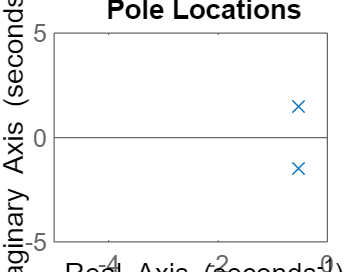

sys = ss(A,B,C,D);
t = 0:0.1:50;
0; 
u = 0*t;
x0 = [1 0];
[y] = lsim(sys,u,t,x0);
pzmap(sys);
title('Pole Locations')
axis([-5,0,-5,5])

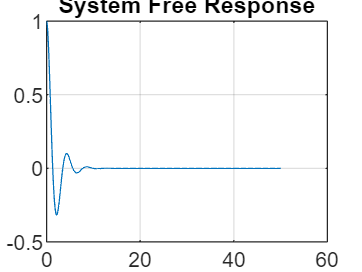

plot(t,y);
grid
xlabel('Time (seconds)')
ylabel('Position of Mass (x(t))')
title('System Free Response')

For further investigation of how to analyze how a system's behavior changes with different parameter values and different inputs, please visit the [Introduction: System Analysis](https://ctms.engin.umich.edu/CTMS/index.php?example=Introduction&section=SystemAnalysis) page.

## 3. System Identification

In this section, we have seen how to model systems using basic physical principles; however, often this is not possible either because the parameters of the system are uncertain, or the underlying processes are simply not understood. In these cases, we must rely on experimental measurements and statistical techniques to develop a system model, a process known as **system identification**. 

System identification may be performed using either time-domain or frequency-domain data, see the [Extras: System Identification](https://ctms.engin.umich.edu/CTMS/index.php?aux=Extras_Identification) page for further details. A couple of system identification activities can also be found from the **Hardware** tab located at the top of pages in the [Controls Tutorial with MATLAB and Simulink](http://ctms.engin.umich.edu) website.

Also refer to MATLAB’s [System Identification Toolbox](http://www.mathworks.com/products/sysid/) for more information on this subject, as well as the “Estimate Process Model” and “Estimate State-Space Model” live editor tasks that you can find in your live script under the “Tasks” menu as seen in the snapshot below. For SISO systems, you can use [the Estimate Process Model ](https://www.mathworks.com/help/ident/ref/estimateprocessmodel.html)task to interactively estimate and validate a process model. [The Estimate State-Space Model](https://www.mathworks.com/help/ident/ref/estimatestatespacemodel.html) task lets you interactively estimate and validate a state-space model using time or frequency data.

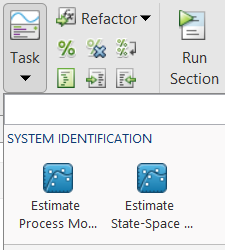

## 4. System Conversions

Most operations in MATLAB can be performed on either the transfer function, the state-space model, or the zero-pole-gain form. Furthermore, it is simple to transfer between these forms if the other representation is required. If you need to learn how to convert from one representation to another, see the [Extras: System Conversions](https://ctms.engin.umich.edu/CTMS/index.php?aux=Extras_Conversions) page. 

## 5. Virtual Hardware and Labs for Control

The Virtual Controls Laboratory contains virtual models of several mechanisms commonly used in controls courses. These virtual mechanisms offer opportunities to visually analyze dynamic systems, identify system parameters, design and test controllers, among others. Instructions for four introductory labs are included. These labs are designed to give an intuitive introduction to basic controls concepts, such as feedback control. Students also have the opportunity to implement and test simple controllers in Simulink. [virtual hardware and labs for controls](https://www.mathworks.com/matlabcentral/fileexchange/100064-virtual-hardware-and-labs-for-controls).

It is a work by